path = dir("G:\My Drive\1. Projects\PHYS-559 Graduate Laboratory (Spring 2023)\NMR Project\Final Paper Data\0.0102M\*.csv")

path = 33×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


sampleConcentration = '0.0102M'

sampleConcentration = '0.0102M'

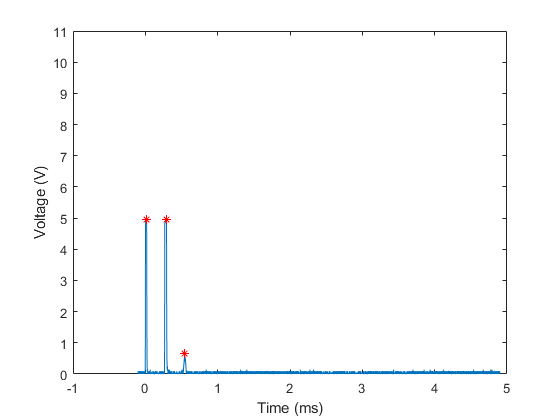

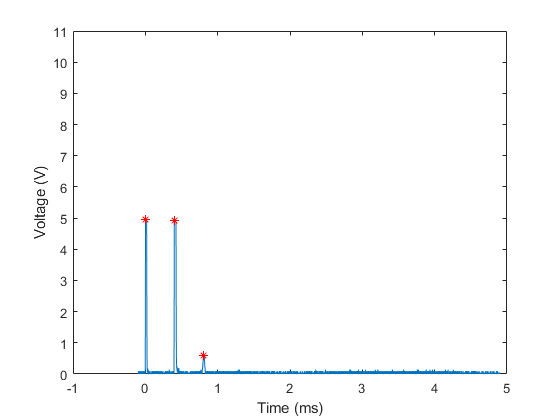

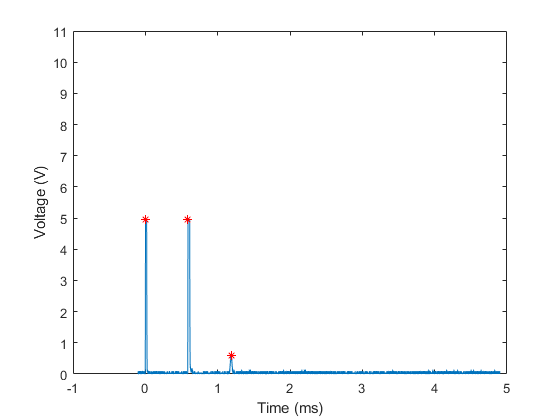

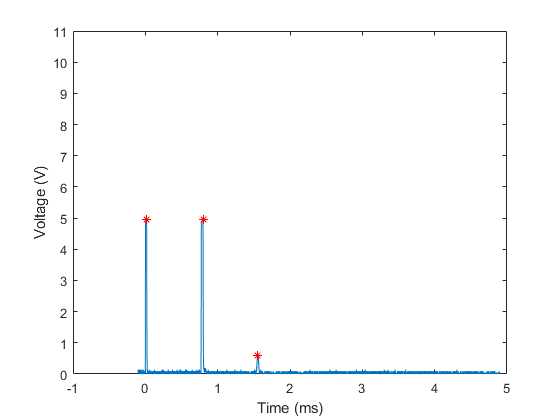

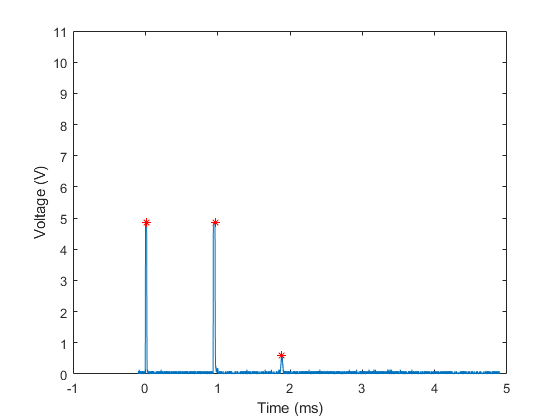

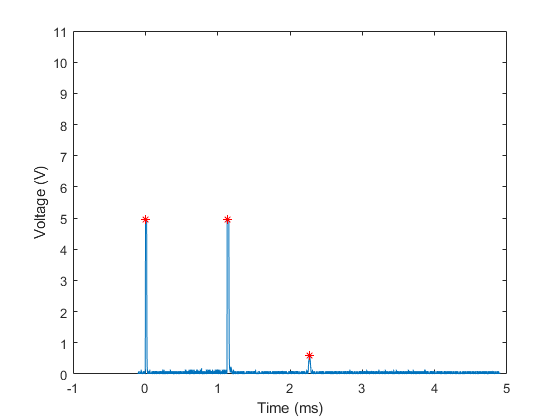

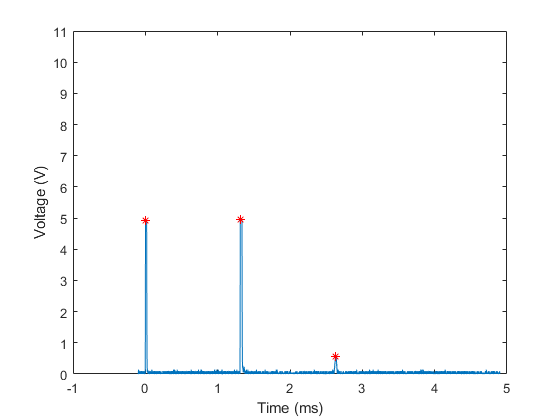

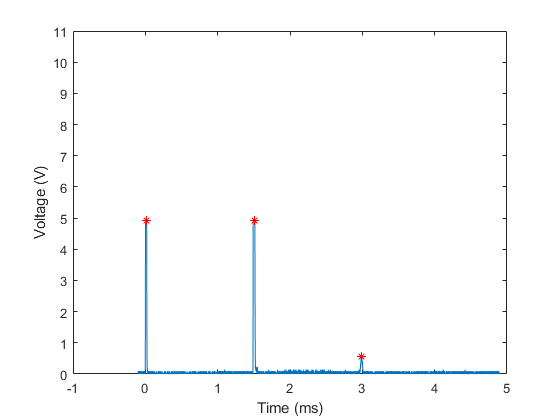

pulse_seperation =     0.2743    0.3982    0.5874    0.7790    0.9450    1.1291    1.3104    1.4960    1.6430    1.8185    2.0117    2.2580    2.2342    2.6303    2.9629    3.2088    3.5478    3.8256    4.2101    4.5956    5.0734    5.5640    6.0308    6.3600    6.6748    7.0410    7.4264    7.7084    8.2244    8.6980


spinEchoAmp =     0.6553    0.6084    0.6084    0.6084    0.6084    0.6084    0.5616    0.5616    0.5616    0.5616    0.5616    0.5616    0.5149    0.5149    0.4212    0.4680    0.4680    0.6553    0.7020    0.6553    0.6553    0.6084    0.6084    0.6084    0.5616    0.5149    0.5149    0.5149    0.5149    0.4212


[pulse_seperation, spinEchoAmp] = NMRdataAnalysis(path,sampleConcentration)

logSpinEchoAmp = log(spinEchoAmp)

logSpinEchoAmp =    -0.4227   -0.4969   -0.4969   -0.4969   -0.4969   -0.4969   -0.5769   -0.5769   -0.5769   -0.5769   -0.5769   -0.5769   -0.6638   -0.6638   -0.8646   -0.7593   -0.7593   -0.4227   -0.3538   -0.4227   -0.4227   -0.4969   -0.4969   -0.4969   -0.5769   -0.6638   -0.6638   -0.6638   -0.6638   -0.8646


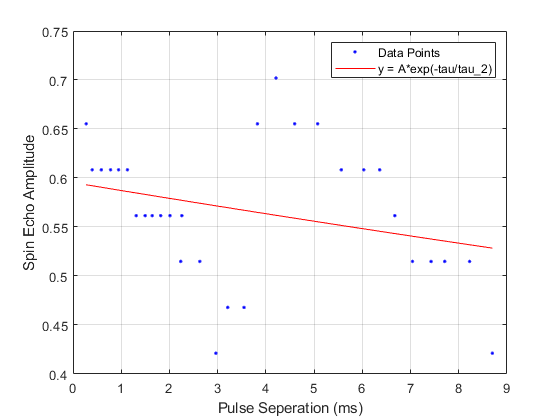

fitresult =      General model:
     fitresult(t) = A*exp(-t/t_2)
     Coefficients (with 95% confidence bounds):
       A =      0.5953  (0.5494, 0.6413)
       t_2 =       72.98  (-22.12, 168.1)

gof = struct with fields:
           sse: 0.1299
       rsquare: 0.0835
           dfe: 28
    adjrsquare: 0.0508
          rmse: 0.0681


[fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)

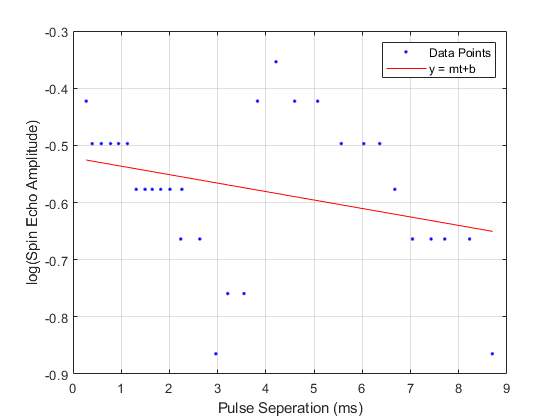

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
       where x is normalized by mean 3.689 and std 2.605
     Coefficients (with 95% confidence bounds):
       p1 =    -0.03856  (-0.08572, 0.008596)
       p2 =     -0.5763  (-0.6227, -0.5299)

gof = struct with fields:
           sse: 0.4304
       rsquare: 0.0911
           dfe: 28
    adjrsquare: 0.0586
          rmse: 0.1240


[fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)

function [fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)
%CREATEFIT(PULSE_SEPERATION,SPINECHOAMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : pulse_seperation
%      Y Output: spinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:36:59


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( pulse_seperation, spinEchoAmp );

% Set up fittype and options.
ft = fittype( 'A*exp(-t/t_2)', 'independent', 't', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.0461713906311539 0.0971317812358475];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'Exponential Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = A*exp(-tau/tau_2)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'Spin Echo Amplitude', 'Interpreter', 'none' );
grid on
end
function [fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)
%CREATEFIT1(PULSE_SEPERATION,LOGSPINECHOAMP)
%  Create a fit.
%
%  Data for 'Linear Fit' fit:
%      X Input : pulse_seperation
%      Y Output: logSpinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:39:47


%% Fit: 'Linear Fit'.
[xData, yData] = prepareCurveData( pulse_seperation, logSpinEchoAmp );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% Plot fit with data.
figure( 'Name', 'Linear Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = mt+b', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'log(Spin Echo Amplitude)', 'Interpreter', 'none' );
grid on
end

